% -----------------------------------------
% ICE Linear Equations
% LiXin
% 2022/3/18
% -----------------------------------------

Problem 1

clear all; close all; clc;
A=[7 9 -9; 3 2 -4; 1 5 -1]; % coefficient matrix
b=[22; 12; -2];
rankA=rank(A)

rankA = 2

rank(A)==rank([A b])

ans = logical
   1


The linear equations have infinite solutions

using pinv()

x=pinv(A)*b

x =     1.6437
   -1.2024
   -2.3684


using '\'

x=A\b

x =    -1.1940
   -1.0448
   -4.4179


using rref

rref_sol=rref([A b])

rref_sol =     1.0000         0   -1.3846    4.9231
         0    1.0000    0.0769   -1.3846
         0         0         0         0


x1=4.9231+1.3846x3, x2=-1.3846-0.0769x3

Problem 2

(a)

clear all; close all; clc;
x=[1; 4; 5];
A=[x.^2 x ones(3,1)];
b=[4; 73; 120];
rankA=rank(A)

rankA = 3

coeff=A\b; % calculate a, b, c
fprintf("a: %f  b: %f  c: %f", coeff(1), coeff(2), coeff(3))

a: 6.000000  b: -7.000000  c: 5.000000

(b)

A=[x.^3 x.^2 x ones(3,1)];
rankA=rank(A)

rankA = 3

The linear equations have infinite solutions

using pinv()

coeff=pinv(A)*b

coeff =     0.2705
    3.2951
    0.8443
   -0.4098


using '\'

coeff=A\b

coeff =     0.2414
    3.5862
         0
    0.1724


using rref

rref_sol=rref([A b])

rref_sol =     1.0000         0         0    0.0500    0.2500
         0    1.0000         0   -0.5000    3.5000
         0         0    1.0000    1.4500    0.2500


a=0.25-0.05d, b=3.5+0.05d, c=0.25-1.45d

Problem 3

clear all; close all; clc;
Ta=150; Tb=20;
syms T1 T2 T3 T4
eqns = [T1==1/3*(Ta+T2+T3);T2==1/2*(T1+T4);T3==1/2*(T1+T4);T4==1/3*(T2+T3+Tb)];
S=solve(eqns,[T1 T2 T3 T4]);
fprintf("T1: %f  T2: %f  T3: %f  T4: %f", S.T1, S.T2, S.T3, S.T4)

T1: 106.666667  T2: 85.000000  T3: 85.000000  T4: 63.333333

A=[1 -1/3 -1/3 0; -1/2 1 0 -1/2; -1/2 0 1 -1/2; 0 -1/3 -1/3 1];
b=[1/3*Ta; 0; 0; 1/3*Tb];
rankA=rank(A)

rankA = 4

rank([A b])

ans = 4

Ts=A\b

Ts =   106.6667
   85.0000
   85.0000
   63.3333


Problem 4

clear all; close all; clc;
Ta=150; Tb=20;
syms T1 T2 T3 T4 T5 T6 T7 T8 T9
eqns=[T1==1/3*(Ta+T2+T4); T2==1/3*(T1+T3+T5); T3==1/2*(T2+T6); T4==1/3*(T1+T5+T7); 
    T5==1/4*(T2+T4+T6+T8);T6==1/3*(T3+T5+T9);T7==1/2*(T4+T8); 
    T8==1/3*(T7+T5+T9); T9==1/3*(Tb+T8+T8)];
s=solve(eqns,[T1 T2 T3 T4 T5 T6 T7 T8 T9]);
fprintf("T1: %f  T2: %f  T3: %f  T4: %f  T5: %f  T6: %f  " + ...
    "\nT7: %f  T8: %f  T9: %f",s.T1,s.T2,s.T3,s.T4,s.T5,s.T6,s.T7, ...
    s.T8, s.T9)

T1: 112.857143  T2: 94.285714  T3: 85.000000  T4: 94.285714  T5: 85.000000  T6: 75.714286  
T7: 85.000000  T8: 75.714286  T9: 57.142857

Problem 5

clear all; close all; clc;

(a)

syms x y z
eqns=[6*x+2*y+10*z==35; 3*x+5*y+2*z==40]

$$eqns = \left(\begin{array}{c} 6\,x+2\,y+10\,z=35\\ 3\,x+5\,y+2\,z=40 \end{array}\right)$$

A=[6 2 10; 3 5 2];
b=[35; 40];
rankA=rank(A)

rankA = 2

rank(A)==rank([A b])

ans = logical
   1


fprintf("doesn't exit a unique solution")

doesn't exit a unique solution

rref_sol=rref([A b])

rref_sol =     1.0000         0    1.9167    3.9583
         0    1.0000   -0.7500    5.6250


x=3.9583-1.9167z, y=5.625+0.75z

(b)

syms x1 z1 y1
eqns=[x1*6+y1*2+z1*10<35 x1*6+y1*2+z1*10>0 x1*3+y1*5+z1*2<40 x1*3+y1*5+z1*2>0]

$$eqns = \left(\begin{array}{cccc} 6\,x_{1}+2\,y_{1}+10\,z_{1}<35 & 0<6\,x_{1}+2\,y_{1}+10\,z_{1} & 3\,x_{1}+5\,y_{1}+2\,z_{1}<40 & 0<3\,x_{1}+5\,y_{1}+2\,z_{1} \end{array}\right)$$

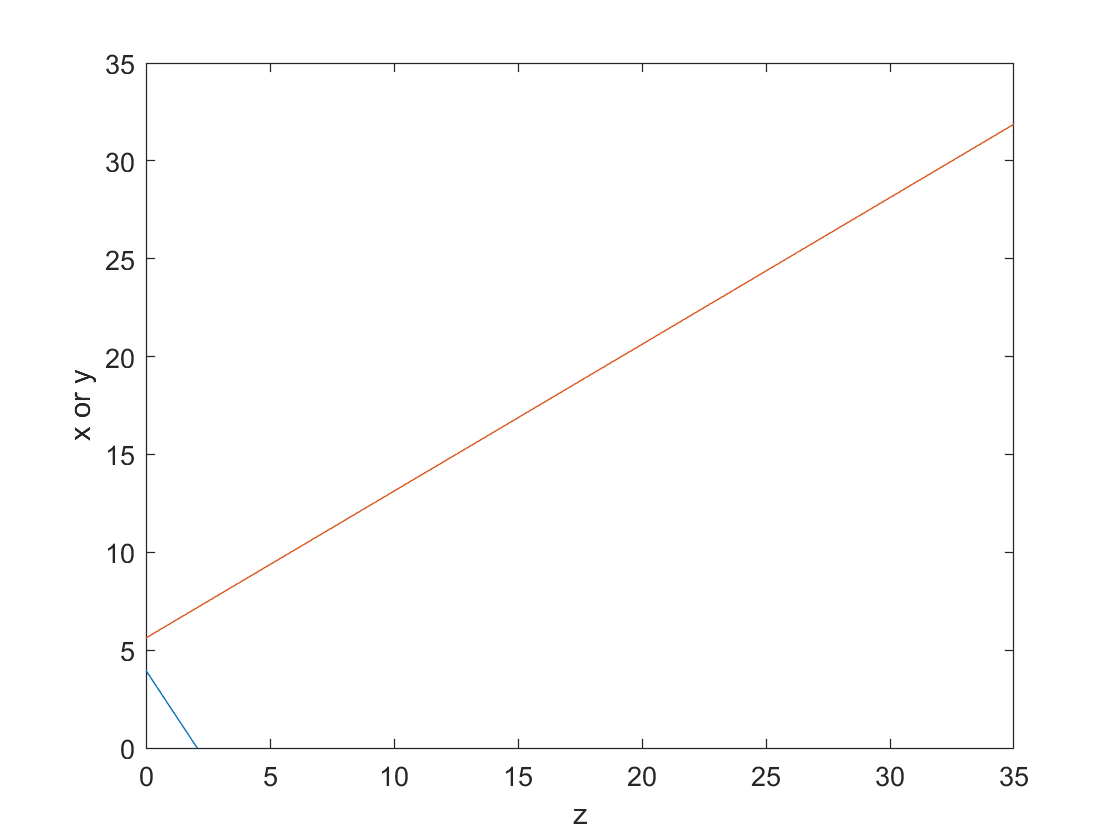

S=solve(eqns, [x1 z1 y1], 'ReturnConditions',true);
z2=0:0.01:35;
x2=3.9583-1.9167*z2;
y2=5.625+0.75*z2;
plot(z2,x2)
hold on
plot(z2,y2)
xlabel('z'), ylabel('x or y'), ylim([0 35])

by solving the equations

0<=z<=2.065

0<=x<=3.9583

5.625<=y<=7.1738

(c)

max=0;
max_x=0; max_y=0; max_z=0;
for z = 0:0.001:2.065
    x=3.9583-1.9167*z;
    y=5.625+0.75*z;
    tempt=200*x+300*y+100*z;
    if tempt > max
        max_x=x;
        max_y=y;
        max_z=z;
        max=tempt;
    end
end
fprintf("the values to maximize profit, x:%.4f y:%.4f z:%.4f",max_x,max_y,max_z)

the values to maximize profit, x:3.9583 y:5.6250 z:0.0000

(d)

max=0;
max_x=0; max_y=0; max_z=0;
for z = 0:0.001:2.065
    x=3.9583-1.9167*z;
    y=5.625+0.75*z;
    tempt=200*x+500*y+100*z;
    if tempt > max
        max_x=x;
        max_y=y;
        max_z=z;
        max=tempt;
    end
end
fprintf("the values to maximize profit, x:%.3f y:%.3f z:%.3f",max_x,max_y,max_z)

the values to maximize profit, x:0.000 y:7.174 z:2.065

Problem 6

clear all; close all; clc;
syms f1 f2 f3 f4 f5 f6 f7
A=[1 0 1 0 0 0 0; 1 -1 0 -1 0 0 0; 
    0 1 0 0 1 0 0; 0 0 1 0 0 1 0; 
    0 0 0 1 0 -1 1; 0 0 0 0 1 0 1];
b=[300; -300; 600; 400; 200; 600];
rankA=rank(A)

rankA = 5

rank([A b])

ans = 5

rref_sol=rref([A b])

rref_sol =      1     0     0     0     0    -1     0  -100
     0     1     0     0     0     0    -1     0
     0     0     1     0     0     1     0   400
     0     0     0     1     0    -1     1   200
     0     0     0     0     1     0     1   600
     0     0     0     0     0     0     0     0


f1=-100+f6, f2=f7, f3=400-f5, f4=200+f6-f7, f5=600-f7